# Building and Manipulating Uncertain Models

This example shows how to use Robust Control Toolbox™ to build uncertain state-space models and analyze the robustness of feedback control systems with uncertain elements. 

We will show how to specify uncertain physical parameters and create uncertain state-space models from these parameters. You will see how to evaluate the effects of random and worst-case parameter variations using the functions `usample` and `robstab`.

## Two-Cart and Spring System

In this example, we use the following system consisting of two frictionless carts connected by a spring `k`:

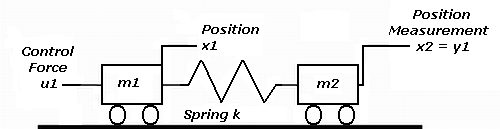

**Figure 1:** Two-cart and spring system.

The control input is the force `u1` applied to the left cart. The output to be controlled is the position `y1` of the right cart. The feedback control is of the following form:


$$u_1 = C(s) (r-y_1)$$


In addition, we use a triple-lead compensator:


$$C(s)=100 (s+1)^3/(0.001s+1)^3$$


We create this compensator using this code:

s = zpk('s'); % The Laplace 's' variable
C = 100*ss((s+1)/(.001*s+1))^3;

## Block Diagram Model

The two-cart and spring system is modeled by the block diagram shown below.

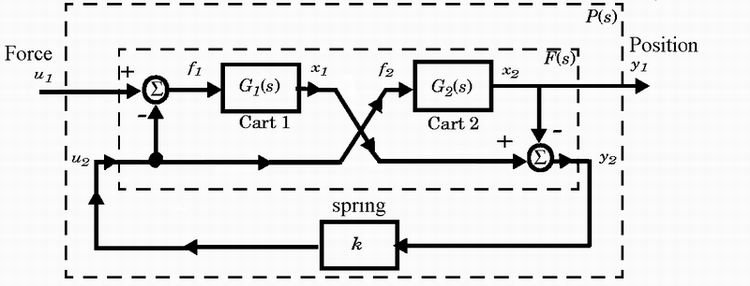

**Figure 2:** Block diagram of two-cart and spring model. 

## Uncertain Real Parameters

The problem of controlling the carts is complicated by the fact that the values of the spring constant `k` and cart masses `m1,m2` are known with only 20% accuracy: $k=1.0 \pm 20\%$ , $m1=1.0 \pm 20\%$ , and $m2=1.0 \pm 20\%$. To capture this variability, we will create three uncertain real parameters using the `ureal` function:

k = ureal('k',1,'percent',20);
m1 = ureal('m1',1,'percent',20);
m2 = ureal('m2',1,'percent',20);

## Uncertain Cart Models

We can represent the carts models as follows: 


$$G_1(s) = \frac{1}{m_1 s^2}, \;\;\; G_2(s) = \frac{1}{m_2 s^2}$$


Given the uncertain parameters `m1` and `m2`, we will construct uncertain state-space models (USS) for G1 and G2 as follows:

G1 = 1/s^2/m1;
G2 = 1/s^2/m2;

## Uncertain Model of a Closed-Loop System

First we'll construct a plant model `P` corresponding to the block diagram shown above (`P` maps u1 to y1):

% Spring-less inner block F(s)
F = [0;G1]*[1 -1]+[1;-1]*[0,G2]

Connect with the spring k 

P = lft(F,k)

The feedback control u1 = C*(r-y1) operates on the plant `P` as shown below:

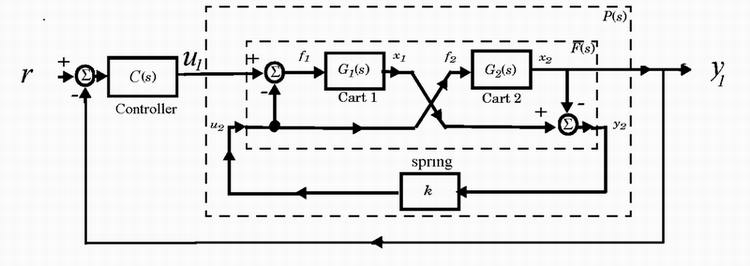

**Figure 3:** Uncertain model of a closed-loop system. 

We'll use the `feedback` function to compute the closed-loop transfer from r to y1. 

% Uncertain open-loop model is
L = P*C

Uncertain closed-loop transfer from r to y1 is

T = feedback(L,1)

Note that since `G1` and `G2` are uncertain, both `P` and `T` are uncertain state-space models.

## Extracting the Nominal Plant

The nominal transfer function of the plant is

Pnom = zpk(P.nominal)

## Nominal Closed-Loop Stability

Next, we evaluate the nominal closed-loop transfer function `Tnom`, and then check that all the poles of the nominal system have negative real parts: 

Tnom = zpk(T.nominal);
maxrealpole = max(real(pole(Tnom)))

## Robust Stability Margin

Will the feedback loop remain stable for all possible values of `k,m1,m2` in the specified uncertainty range? We can use the `robstab` function to answer this question rigorously.

% Show report and compute sensitivity
opt = robOptions('Display','on','Sensitivity','on');
[StabilityMargin,wcu] = robstab(T,opt);

The report indicates that the closed loop can tolerate up to three times as much variability in `k,m1,m2` before going unstable. It also provides useful information about the sensitivity of stability to each parameter. The variable `wcu` contains the smallest destabilizing parameter variations (relative to the nominal values).

wcu

## Worst-Case Performance Analysis

Note that the peak gain across frequency of the closed-loop transfer `T` is indicative of the level of overshoot in the closed-loop step response. The closer this gain is to 1, the smaller the overshoot. We use `wcgain` to compute the worst-case gain `PeakGain` of `T` over the specified uncertainty range.

[PeakGain,wcu] = wcgain(T);
PeakGain

Substitute the worst-case parameter variation `wcu` into `T` to compute the worst-case closed-loop transfer `Twc`.

Twc = usubs(T,wcu);         % Worst-case closed-loop transfer T

Finally, pick from random samples of the uncertain parameters and compare the corresponding closed-loop transfers with the worst-case transfer `Twc`.

Trand = usample(T,4);         % 4 random samples of uncertain model T
clf
subplot(211), bodemag(Trand,'b',Twc,'r',{10 1000});  % plot Bode response
subplot(212), step(Trand,'b',Twc,'r',0.2);           % plot step response

**Figure 4:** Bode diagram and step response. 

In this analysis, we see that the compensator C performs robustly for the specified uncertainty on k,m1,m2.

*Copyright 1986-2012 The MathWorks, Inc.*